% Clear Workspace
clear all
clc

% Read STL File
% stl1 = stlread("Test Objects\cubeWithHole.STL");
% stl1 = stlread("Test Objects\cylinder.STL");
% stl1 = stlread("Test Objects\Case.STL");
% stl1 = stlread("Test Objects\box.STL");
% stl1 = stlread("Test Objects\keys.STL");
stl1 = stlread("Test Objects\Witcher_towel_hook.stl");

trisurf(stl1)
hold on

% Create UniformSliceGeneratorObject
sliceHeight = 0.5;
uSGO1 = FlatUniformSliceGenerator(stl1, sliceHeight)

uSGO1 =   FlatUniformSliceGenerator with properties:

                 obj: []
    connectivityList: [2306×3 double]
       numOfElements: 2306
              points: [1155×3 double]
      sliceThickness: 0.5000
           slicePath: []
           slicerTol: 1.0000e-05


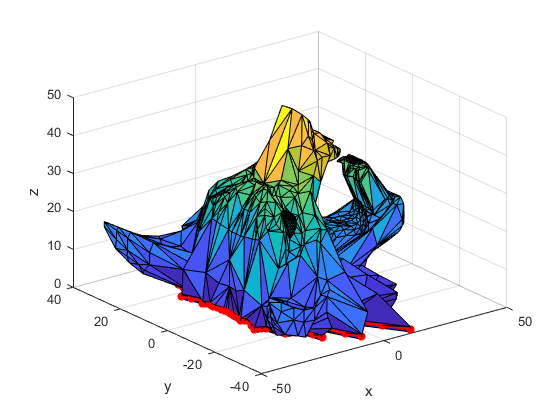


% Manual Slice for Debugging - Comment out if not used.
test = uSGO1.slicePathLayer(1);
for j = 1:max(test(:,4))

    pathPlotPoints = test(test(:,4) == j,:);
    plot3(pathPlotPoints(:,1), pathPlotPoints(:,2), pathPlotPoints(:,3),'-r*','LineWidth',2);
    hold on

end
xlabel('x')
ylabel('y')
zlabel('z')

% Generate
view(3);

figure(3)
op = uSGO1.getSlicePath()

op =    -1.2159   24.1453    0.5000    1.0000
   -4.6395   33.8264    0.5000    1.0000
   -5.4896   36.2301    0.5000    1.0000
   -9.8952   27.6036    0.5000    1.0000
  -10.9891   25.4617    0.5000    1.0000
  -12.3618   26.3722    0.5000    1.0000
  -12.7026   26.5983    0.5000    1.0000
  -14.0473   27.9990    0.5000    1.0000
  -14.3812   28.3468    0.5000    1.0000
  -15.8940   30.1117    0.5000    1.0000


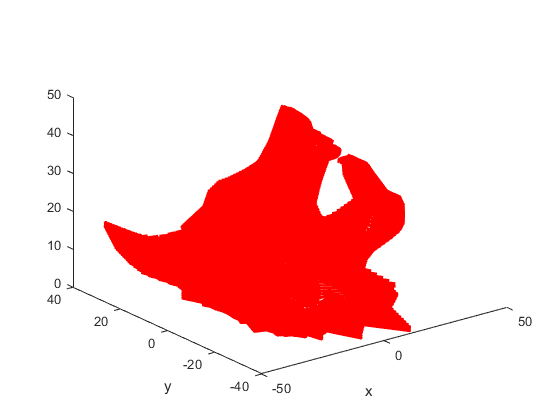


% Show
figure(4)

for i = 0:sliceHeight:double(max(op(:,3)))
    
    zPlotPoints = op(op(:,3) == i,:);
    
    for j = 1:max(zPlotPoints(:,4))
    
        pathPlotPoints = zPlotPoints(zPlotPoints(:,4) == j,:);
        plot3(pathPlotPoints(:,1), pathPlotPoints(:,2), pathPlotPoints(:,3),'-r','LineWidth',2);
        hold on

    end

end

xlabel('x')
ylabel('y')
view(3);
hold on